# "Laser scan" line fit example

clear
clc

rosshutdown

Shutting down global node /matlab_global_node_74308 with NodeURI http://192.168.7.12:53714/


setenv('ROS_MASTER_URI','http://192.168.7.34:11311')
setenv('ROS_IP','192.168.7.12')
rosinit('http://192.168.7.34:11311','NodeHost','192.168.7.12');

Initializing global node /matlab_global_node_80324 with NodeURI http://192.168.7.12:53756/


scansub = rossubscriber('/scan');
linescan = receive(scansub); %Receive message
% rangesScan = linescan.Ranges; % Extract scan
% angles = linescan.AngleMin:linescan.AngleIncrement:linescan.AngleMax;

scan = linescan

scan =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -0.5216
          AngleMax: 0.5243
    AngleIncrement: 0.0016
     TimeIncrement: 0
          ScanTime: 0.0330
          RangeMin: 0.4500
          RangeMax: 10
            Ranges: [640×1 single]
       Intensities: [0×1 single]

  Use showdetails to show the contents of the message



ranges = scan.Ranges;
angles = scan.readScanAngles;
size(ranges)

ans =    640     1


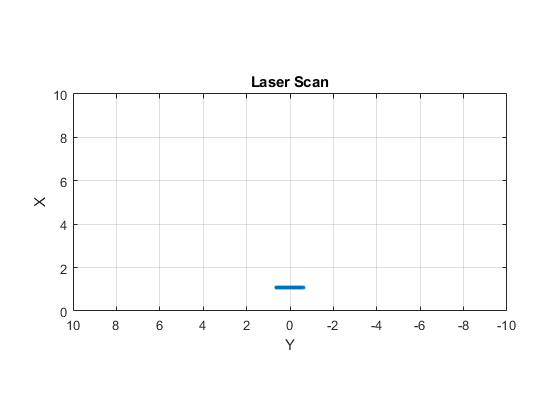


plot(scan)

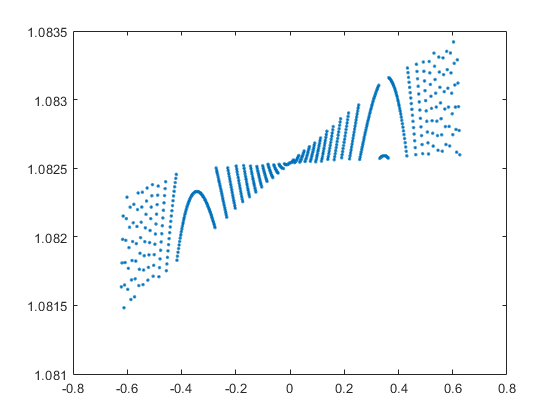


% get data from scan
cart = readCartesian(scan);
figure()
plot(cart(:,2), cart(:,1), '.') % note - y before x..


x = cart(:,2); % x-pos
d = cart(:,1); % depth

## Fitting one line..

% only left side
xleft = x(100:200)

xleft =    -0.4067
   -0.4047
   -0.4027
   -0.4007
   -0.3987
   -0.3966
   -0.3946
   -0.3926
   -0.3907
   -0.3887


dleft = d(100:200)

dleft =     1.0820
    1.0820
    1.0820
    1.0820
    1.0821
    1.0821
    1.0821
    1.0821
    1.0821
    1.0822


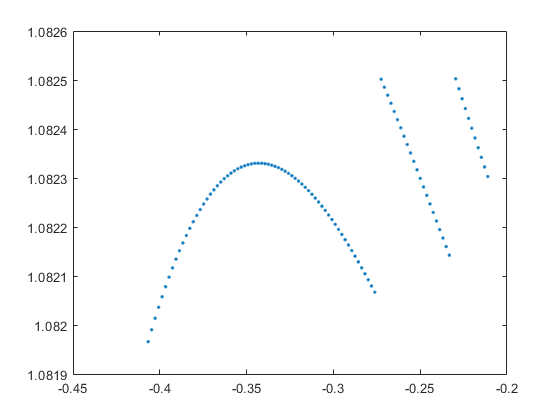

plot(xleft, dleft, '.')


mdl = fitlm(xleft,dleft);
coef=mdl.Coefficients.Estimate

coef =     1.0825
    0.0009


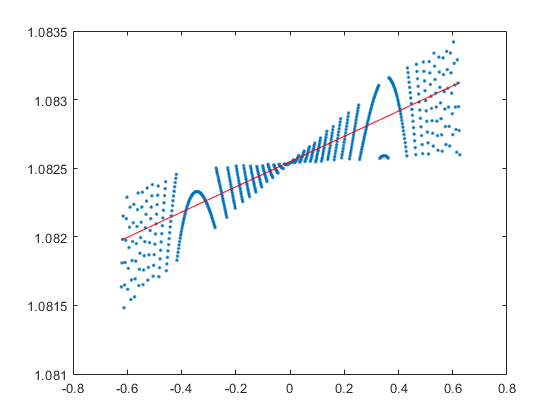


plot(x,d, '.'), hold on
plot(x, coef(1) + coef(2)*x, 'r')

## Multi-line method..

N = 100 % grid size

N = 100


xoffset = min(x)

xoffset = -0.6216

xscale = (max(x)-min(x))

xscale = 1.2476

xi = (x - xoffset)/xscale; % scale to 0-1
xi = round(xi*(N-1))+1; % scale and integer 1 to N
di = (d - min(d))/(max(d)-min(d)); % scale to 0-1
di = round(di*(N-1))+1;
ind = sub2ind([N N], xi, di) % matrix indices

ind =          801
        1701
        2501
        3402
           2
         802
        1702
        2502
        3302
        4103


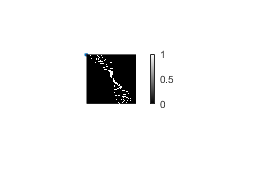


mat = zeros(N); % NxN matrix
mat(ind) = 1; % with points..

imshow(mat), colorbar()

## Hough transform

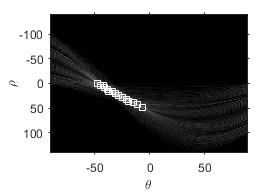

[H,theta,rho] = hough(mat);

% Hough peaks
Nlines = 15; % Note - Nlines peaks/lines !
P  = houghpeaks(H,Nlines); 
imshow(H,[],'XData',theta,'YData',rho,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
plot(theta(P(:,2)),rho(P(:,1)),'s','color','white');

## Hough lines

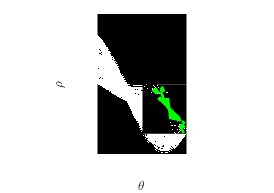

lines = houghlines(mat,theta,rho,P,'FillGap',5,'MinLength',7);

imshow(mat), hold on,
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end


lines(2)

ans = struct with fields:
    point1: [80 75]
    point2: [86 80]
     theta: -45
       rho: 4
